# DSZOB, cvičenie 9.

## **Zadanie:**

## **Úloha 1 Odstránenie šumu z 2D signálu (obraz) v priestorovej doméne**

Z obrázka, ktorý obsahuje šum typu “salt and pepper”, odstráňte tento šum. Použite pri tom konvolúciu s týmito filtračnými jadarmi:

- Medián

- Gauss

- Mean

Zodpovedzte nasledujúce otázky:

Ktorý z týchto filtrov je najvhodnejší na odstránenie šumu typu “salt and pepper” a prečo ?

Ktorý z týchto filtrov najviac zachováva hrany v obrázku, a ktorý najmenej?** Zdôvodnite !**

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

% Riesenie / Solution
clear;

sap1 = imread('Asignments\Assignment_8\salt_and_pepper.png');
sap1 = rgb2gray(sap1);
sap2 = imread('Asignments\Assignment_8\salt_and_pepper2.png');


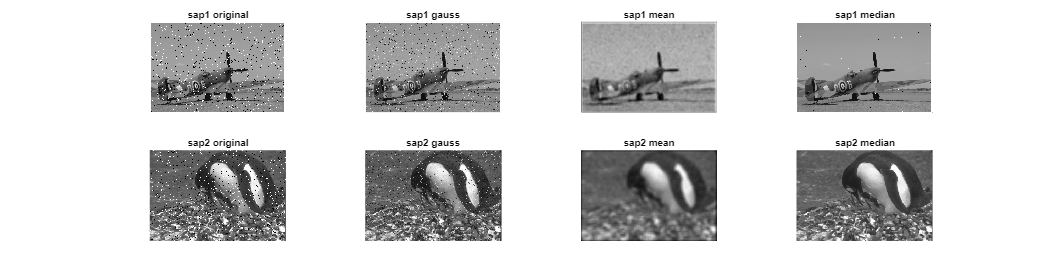

close all;
foo = figure('Position', [100, 100, 2024, 524]);

subplot(2,4,1);
imshow(sap1, []);
title("sap1 original");

subplot(2,4,2);
imshow(conv2(sap1, fspecial("gaussian", [11, 11]), "same"), []);
title("sap1 gauss");

subplot(2,4,3);
imshow(conv2(sap1, fspecial("average", [11,11]), "same"), []);
title("sap1 mean");

subplot(2,4,4);
imshow(medfilt2(sap1), []);
title("sap1 median");

subplot(2,4,5);
imshow(sap2, []);
title("sap2 original");

subplot(2,4,6);
imshow(conv2(sap2, fspecial("gaussian", [11,11]), "same"), []);
title("sap2 gauss");

subplot(2,4,7);
imshow(conv2(sap2, fspecial("average", [11,11]), "same"), []);
title("sap2 mean");

subplot(2,4,8);
imshow(medfilt2(sap2), []);
title("sap2 median");

Median filter is a clear winner here, it gets rid of most of the salt and pepper noise while keeping the edges sharp, second best is the mean filter which got rid of the nosie, but in the process blurred the image quite a lot. Gauss filter didn't do a good job of filtering the noise in the first image, in the second image it did a slightly better job but still worse compared to the other two filters. We could argue that the gauss filter in second picture is better than the mean filter in the sense, that it blurs the image less. We tried different sizes of kernels, anything in range of 3x3 to 101x101 with gauss filter didnt make much of a difference. 

## **Úloha 2 Odstránenie šumu z 2D signálu (obraz) v spektre**

Vizualizujte spektrum obrazu s periodickým šumom. Navrhnite podľa pozície dominantných vrcholov v spektre filter, pomocou ktorého vo výsledku odstránite periodický šum z obrazu. Filtráciu vykonajte pre všetky obrázky na dokumentovom serveri s periodickým šumom. Spekturm umožnite filtrovať interaktívne - používateľ bude mať možnosť kliknutím vybrať miesto v spektre, ktoré má byť vyfiltrované.

Filtrujte nasledovnými spôsobmi:

Umožnite zo spektra vymazať (vynulovať) okolie miesta, na ktoré bolo kliknuté (ľavé stlačenie myši). Využite symetriu, aby ste odstránili rovnaké miesto aj vo zvyšných kvadrantoch. Vymažte zo spektra kružnicu, ktorá bude mať stred v strede spektra a polomer určený vzdialenosťou od stredu k miestu, na ktoré bolo kliknuté (pravé stlačenie myši) ako na obrázku nižšie.

Kružnicu vytvorte tak, aby bola typu BandPass podobná Gaussovmu filtru. Vytvoríte ju napríklad ako ideálny BandPass filter a následnou konvolúciou s Gaussovym filtrom ju rozmažete.

**Zodpovedzte nasledujúce otázky:**

Prečo je vhodné používateľovi umožniť zo spektra vymazať celú kružnicu ? (pomôcka: symetria).

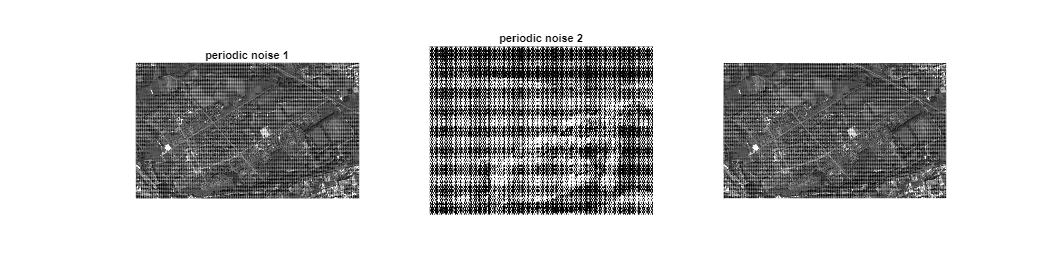

% Riesenie / Solution
% log(abs(fft2(image)))
close all;
foo = figure('Position', [100, 100, 2024, 524]);

per1 = imread('Asignments\Assignment_8\periodic_noise1.jpg');
per2 = imread('Asignments\Assignment_8\periodic_noise2.jpg');
per3 = imread('Asignments\Assignment_8\periodic_noise3.jpg');

subplot(1,3,1);
imshow(per1, []);
title("periodic noise 1");

subplot(1,3,2);
imshow(per2, []);
title("periodic noise 2");

subplot(1,3,3);
imshow(per3, []);
title("periodic noise 3");
imshow(per1, []);

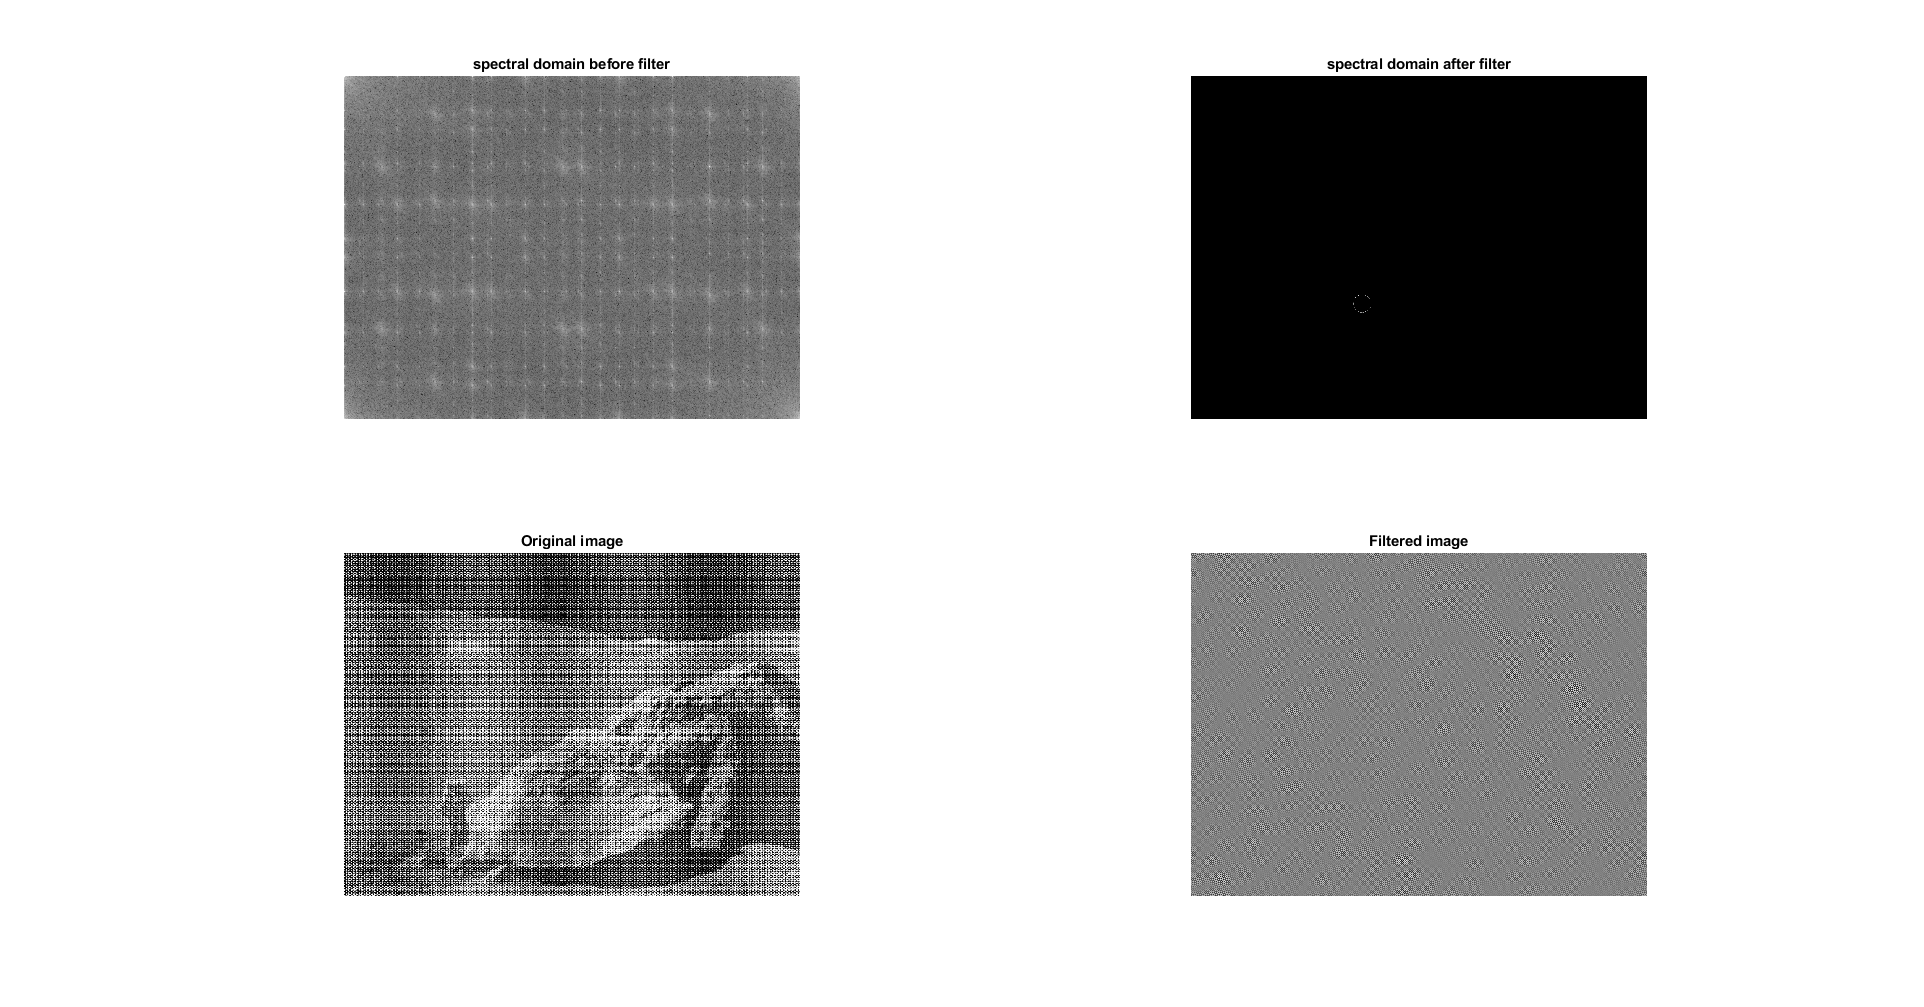

close all;
interactivePointFilter(per2, 20);

% Functions

function ret = deletePoint(img, inX, inY, r)
    width = length(img);
    height = length(img(:,1));
    toRet = zeros(height, width);
    for y = 1:width
        for x = 1:height
            if ((x - inY))^2 + (y - inX)^2 < r^2
                toRet(x,y) = 0;
            else 
                toRet(x,y) = img(x, y);
            end
        end
    end
    ret = toRet;
end

function ret = deleteBand(img, inX, inY, r)
    width = length(img);
    height = length(img(:,1));
    toRet = zeros(height, width);
    rad = sqrt((round(width/2) - inX)^2 + (round(height/2) - inY)^2);
    for y = 1:width
        for x = 1:height
            if ((x - round(width/2)))^2 + (y - round(height/2))^2 > rad + r || ((x - round(width/2)))^2 + (y - round(height/2))^2 < rad - r
                toRet(x,y) = 0;
            else 
                toRet(x,y) = img(x, y);
            end
        end
    end
    ret = toRet;
end

function ret = interactivePointFilter(img, r)
% Main
% Initialize a variable to store the inputs
    inputs = [];
    escape_loop = false;

    close all;
    foo = figure('Position', [100, 100, 2024, 1048]);

    subplot(2,2,1);
    bar = fft2(img);
    imshow(log(abs(bar)), []);
    title("spectral domain before filter");

    % Start the loop
    while 1
        if escape_loop
            break;
        end
        % Get the mouse coordinates and button click
        try
            [x, y, button] = ginput(1);
            if button == 2
                break;
            end
            % If the left mouse button was clicked, store the input
            if button == 1
                % Filtering logic
                bar = deletePoint(bar, x, y, r);
            end
            if button == 3
                bar = deleteBand(bar, x, y, r);
            end

            subplot(2,2,2);
            imshow(log(abs(bar)), [])
            title("spectral domain after filter");
        catch 
        end   




        % If the letter H is pressed on the keyboard, exit the loop
        if get(gcf, 'CurrentKey') == 'h'
            escape_loop = true;
        end



    end

    subplot(2,2,3);
    imshow(img, []);
    title("Original image");

    subplot(2,2,4);
    imshow(ifft2(bar), []);
    title("Filtered image");
end

